# Mean and Variance as Data Descriptors

Note: this script reproduces the figure on summarizing statistics in Section 1.3.3 of **Statistics for Chemical Engineers**: two data sets with different mean and variance. Victor Z UW-Madison, 2020 example of empirical mean and variance as data descriptors

clc; clear all; close all hidden;

## First data set

Note: mean 6 and variance 1. generate first dataset

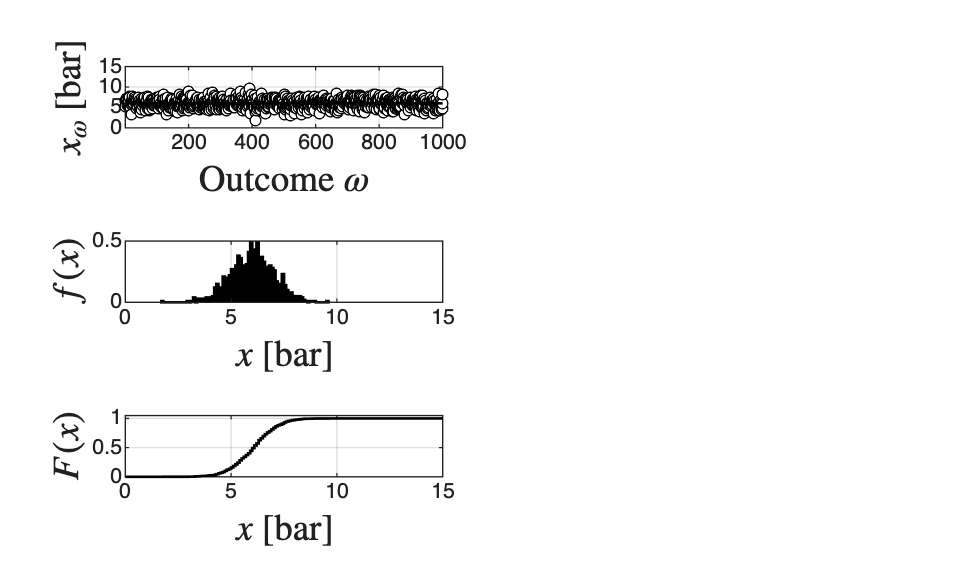

N=1000;
X1=normrnd(6,1,N,1);

% compare pdf and cdf of pressure
figure(1)
% outcomes
subplot(3,2,1)
plot(X1,'blacko','MarkerFaceColor','w','MarkerSize',4)
hold on
plot(1:N,linspace(6,6,N),'LineWidth',1,'Color','black')
xlabel('Outcome $\omega$','Interpreter','latex','FontSize',14)
ylabel('$x_\omega$ [bar]','Interpreter','latex','FontSize',14)
grid on
axis([1 N 0 15])

% can also automatically visualize empirical pdf using histogram
subplot(3,2,3)
histogram(X1,'BinWidth',0.1,'Normalization','pdf','EdgeColor','black','FaceColor','none','LineWidth',1)
xlabel('$x$ [bar]','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
axis([0 15 0 0.5])
grid on

% compute and plot empirical cdf 
t=0:0.1:15;
for i=1:length(t) 
    F(i)=0;
    for j=1:length(X1)
        F(i)=F(i)+(X1(j)<=t(i));
    end
end
F=F/N;
subplot(3,2,5)
stairs(t,F,'LineWidth',1,'Color','black')
xlabel('$x$ [bar]','Interpreter','latex','FontSize',14)
ylabel('$F(x)$','Interpreter','latex','FontSize',14)
title('')
grid on
axis([0 15 0 1.05])

## Second data set

Note: mean 9 and variance 2. generate second datasets

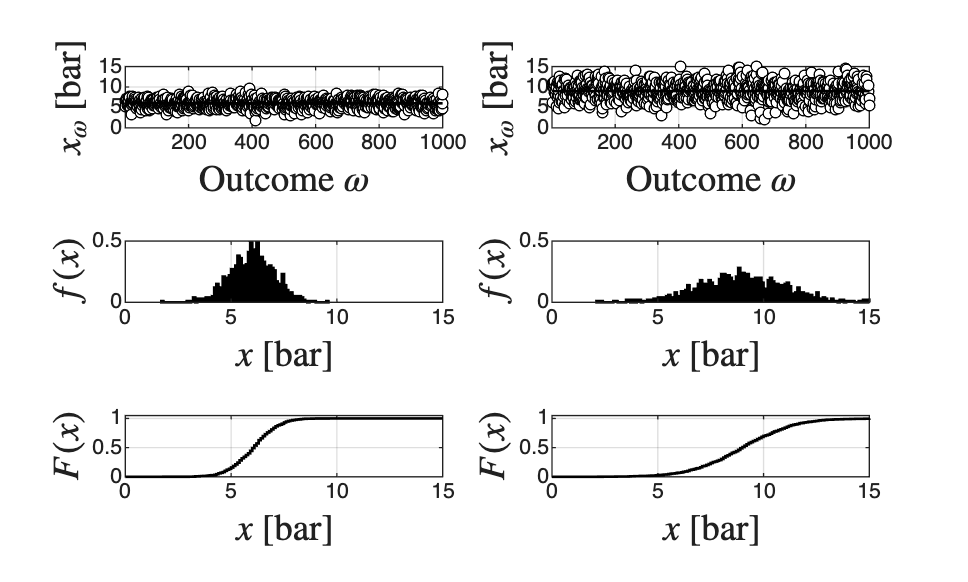

N=1000;
X1=normrnd(9,2,N,1);

% compare pdf and cdf of pressure
figure(1)
% outcomes
subplot(3,2,2)
plot(X1,'blacko','MarkerFaceColor','w','MarkerSize',4)
hold on
plot(1:N,linspace(9,9,N),'LineWidth',1,'Color','black')
xlabel('Outcome $\omega$','Interpreter','latex','FontSize',14)
ylabel('$x_\omega$ [bar]','Interpreter','latex','FontSize',14)
grid on
axis([1 N 0 15])

% can also automatically visualize empirical pdf using histogram
subplot(3,2,4)
histogram(X1,'BinWidth',0.1,'Normalization','pdf','EdgeColor','black','FaceColor','none','LineWidth',1)
hold on
plot(linspace(9,9,N),1:N,'LineWidth',1,'Color','black')
xlabel('$x$ [bar]','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
axis([0 15 0 0.5])
grid on

% compute and plot empirical cdf 
t=0:0.1:15;
for i=1:length(t) 
    F(i)=0;
    for j=1:length(X1)
        F(i)=F(i)+(X1(j)<=t(i));
    end
end
F=F/N;
subplot(3,2,6)
stairs(t,F,'LineWidth',1,'Color','black')
xlabel('$x$ [bar]','Interpreter','latex','FontSize',14)
ylabel('$F(x)$','Interpreter','latex','FontSize',14)
title('')
grid on
axis([0 15 0 1.05])
print -depsc ch1_mean_var_descriptors.eps 

## Note

The mean tells us where the data are located and the variance how spread out they are; together they give a quick summary of a random phenomenon.